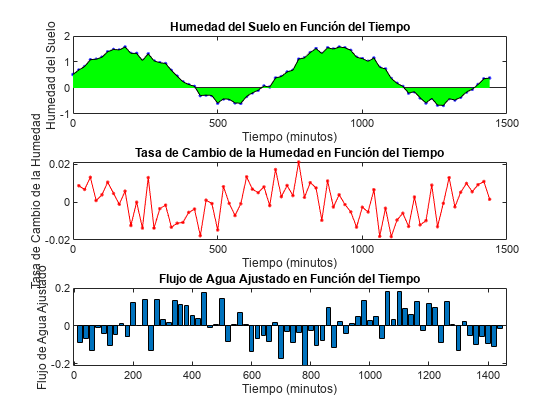

clc
clear all
% aleatorizar humedad en un plazo de 24h con muestras cada 20 min
tiempo = 0:20:1440*1; % Tiempo en minutos (24 horas, una muestra cada 20 minutos)
humedad = sin(2*pi*tiempo/720) + 0.5 + 0.1*randn(size(tiempo)); % Simulación de humedad del suelo
% tasa de cambio de la humedad
tasa_cambio = diff(humedad) ./ diff(tiempo);
% calcular la integral definida para obtener la cantidad total de agua
cantidad_agua = trapz(tiempo(2:end), tasa_cambio);
%Ajustar el flujo de agua
k = -0.1; % Constante del sistema
area_riego = 100; % Área de riego en metros cuadrados
flujo_agua = k * area_riego * cantidad_agua;
figure;
subplot(3, 1, 1);
plot(tiempo, humedad, 'b.-');
hold on
area(tiempo, humedad,'FaceColor','g');
hold off
title('Humedad del Suelo en Función del Tiempo');
xlabel('Tiempo (minutos)');
ylabel('Humedad del Suelo');
subplot(3, 1, 2);
plot(tiempo(2:end), tasa_cambio, 'r.-');
title('Tasa de Cambio de la Humedad en Función del Tiempo');
xlabel('Tiempo (minutos)');
ylabel('Tasa de Cambio de la Humedad');
subplot(3, 1, 3);
bar(tiempo(2:end), k * area_riego * tasa_cambio);
title('Flujo de Agua Ajustado en Función del Tiempo');
xlabel('Tiempo (minutos)');
ylabel('Flujo de Agua Ajustado');

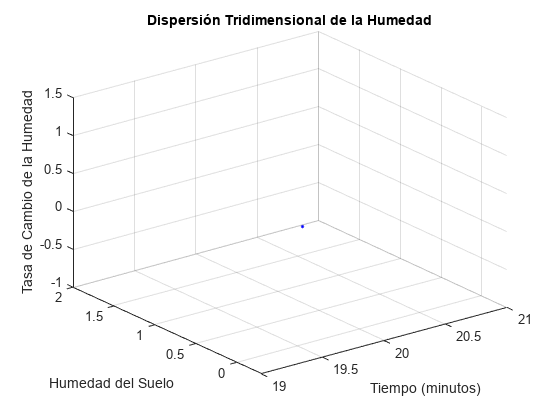


% Crear coordenadas tridimensionales (x, y, z)
x = tiempo(2:end);  % tiempo
y = humedad(2:end); % humedad
z = tasa_cambio;    % tasa de cambio de la humedad

% Crear figura para la animación
figure;

for i = 1:length(x)
    % Graficar dispersión tridimensional
    scatter3(x(1:i), y(1:i), z(1:i), 'b.');
    
    % Ajustar las propiedades del gráfico
    title('Dispersión Tridimensional de la Humedad');
    xlabel('Tiempo (minutos)');
    ylabel('Humedad del Suelo');
    zlabel('Tasa de Cambio de la Humedad');
    grid on;

    % Pausa para la animación
    pause(0.1);
end


% Análisis estadístico adicional después de la animación
media_temporal = mean(z);
desviacion_temporal = std(z);
correlacion_matrix = corrcoef([x(:), y(:), z(:)]);
modelo_regresion = fit([x(:), y(:)], z(:), 'poly23');
varianza_espacial = var(z, 0, 2);

% Imprimir resultados en la consola
disp('Resultados del Análisis Estadístico:');

Resultados del Análisis Estadístico:


disp(['Media Temporal: ' num2str(media_temporal)]);

Media Temporal: -9.5034e-05


disp(['Desviación Estándar Temporal: ' num2str(desviacion_temporal)]);

Desviación Estándar Temporal: 0.0092887


disp('Coeficientes de Correlación:');

Coeficientes de Correlación:


disp(correlacion_matrix);

    1.0000   -0.3679   -0.0120
   -0.3679    1.0000    0.1276
   -0.0120    0.1276    1.0000



disp(['Varianza Espacial: ' num2str(varianza_espacial)]);

Varianza Espacial: 8.628e-05


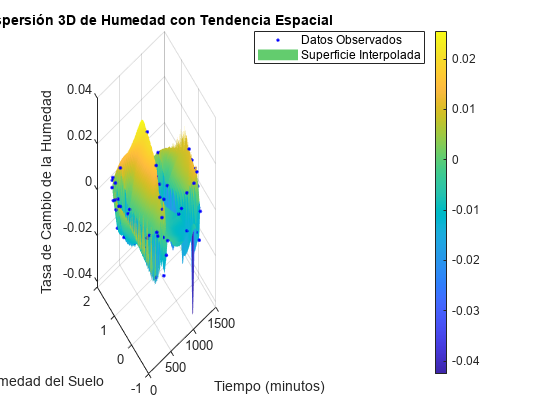


% Visualización de la superficie interpolada
[X_interp, Y_interp] = meshgrid(linspace(min(x), max(x), 100), linspace(min(y), max(y), 100));
Z_interp = griddata(x(:), y(:), z(:), X_interp, Y_interp, 'cubic');

% Gráfico de dispersión y superficie interpolada
figure;
scatter3(x(:), y(:), z(:), 'b.');
hold on;
surf(X_interp, Y_interp, Z_interp, 'EdgeColor', 'none');
title('Dispersión 3D de Humedad con Tendencia Espacial');
xlabel('Tiempo (minutos)');
ylabel('Humedad del Suelo');
zlabel('Tasa de Cambio de la Humedad');
legend('Datos Observados', 'Superficie Interpolada');
hold off;

colorbar